# Filter Comparisons for Noise Removal in Digital Images

Shizhen Li, 20785413

Arjun Bawa, 20711916

Published on Dec 23, 2021

## Abstract

In 2008, James C. Church, Yixin Chen, Stephen V. Rice proposed Spatial Median Filter (SMF) and a modified version of it for noise removal in digital images [1]. In the paper, they performed various experiments comparing SMF with other popular noise removal filters in their performance on different level of image data corruption. In this article, we repeated their experiment on a different set of image data, and obtained similar result as presented in the original paper.

## 1.    Problem Formulation

Digital cameras have become popular around the world for their easy-to-use, inexpensiveness, and great mobility over internet and other digital media. However, when each digital image is taken, an error-prone transmission is needed from the photon sensors to the local storage of the camera. To reduce the errors caused by the noise on this transmission, extensive research has been performed on this subject.

## 2.    Proposed Solution

### 2.1.    Spatial Median Filter (SMF)

In the article "A Spatial Median Filter for Noise Removal in Digital Images", Chuch et. al. proposed SMF and modified SMF as a competitive method of software smoothing algorithm to remove noises from digital images.

As a smoothing algorithm, SMF involves the same general steps as other smoothing algorithms:

- Receive the noise-corrupted image from workflow upstream.

- Apply a mask of specific size on each pixel of the image, which give the concerned pixels around the center pixel.

- Perform calculations on the concerned pixels, and write the result to the respective position on the reconstructed image, this is where different smoothind algorithms differ from others.

- Complete step 2 and 3 for all pixels in the image to complete the algorithm, and then send to workflow downstream.

The idea of spatial depth is centric to SMF. A spacial depth of a certain pixel to other pixels concerned is as follows:

$S_{depth}(p, S_1, ..., S_N) = 1 - \frac{1}{N-1}\left\|\sum_{i=1}^N \frac{p - S_i}{\left\| p - S_i \right\|} \right\|$ [1]

The spatial depth gives a measure of how other pixels in the group are generally at compared to the current pixel. The smaller the value is, means the direction other pixels are at is more unanimous relative to current pixel, which signals that the pixel likely does not belong to the central position.

In terms of workflow, the process of calculating spatial depth is:

- Computing the difference of the pixel to other pixels, and normalize it to unit length

- Take the **vector** summation of the normalized difference vectors, then find the sum's norm

- Devide this norm by number of other pixels (to avoid negative numbers), then be substracted by 1.

Our implementation of spatial depth calculation is pairwise, computing for each pixel to each other pixel within the concerned pixels under the mask. Since we do not care about the actual value of spatial depth but rather a comparison between them, our spatial depth function only calculate $\xi =\left\|\sum_{i=1}^N \frac{p-S_i }{\left\|p-S_i \right\|}\right\|$, as the other parts of the equation is the same for all pixels withing the set. It is easy to prove that the smaller $\xi$ is, the larger the spatial depth will be. The specific code and explanatory comments are attached in `sdepth.mlx` [2].

After spatial depth is calculated, the pixel with the maximum spatial depth (minimum $\xi$) is chosen to represent the center pixel in the output image, which is reasonable as large spatial depth means other pixels in the group are more uniformly around this pixel. Our implementation of SMF is attached in `SMF.mlx` [3].

### 2.2.    Modified Spatial Median Filter (mSMF)

In the original paper, the authors pointed out that a major problem with other filters including SMF is that they all perform "universal replacement" [1]. Each pixel need to go through the filter algorithm without considering whether the pixel is corrupted or not. Specifically, sometimes a pixel, even with a very large spatial depth, is still replaced by another pixel who had even larger spatial depth, even though the original pixel is highly likely not corrupted.

Therefore, the authors suggested adding an additional parameter $T$ to SMF [1]. The parameter $T$ is a threshold value at which we decide whether a pixel is to be corrected with algorithm or not. If a pixel is among the top $T$ largest spatial depths (top $T$ $\Leftrightarrow$ smallest $\xi$) in the whole group, the algorithm will not perform replacement and retain its value. This can potentially avoid lots of false replacement in the filter. Our implementation of MSMF is attached in `MSMF.mlx` [4].

## 3.    Reference Solutions

As a widely researched area, there are a lot of other competitive smoothing algorithms for noise removal. In the original paper, the author compared SMF with 4 other filters, namely, Mean Filter, Simple Median Filter, Component Median Filter (CMF), and Vector Median Filter (VMF).

### 3.1.    Mean Filter

The Mean filter is the most straight forward filter. The resulting pixel's each component (red, green, blue) takes their value from the mean value of the respective component of all concerned pixels. The specific formula is:


$$MeanFilter(x_1,...x_N) = \frac{1}{N} \sum_{i=1}^N x_i$$


Our exact implementation of this filter along with a more detailed explanation of the algorithm is attached in the script file `MeanFilter.mlx` [5].

### 3.2.    Median Filter

The simple Median filter will sort the concerned pixels by their L2-norms. Generally speaking, the mask will pick out an odd number of pixels. The median filter will find the median pixel of the concerned pixels and use it as the pixel for replacement. The specific formula is:


$$MedianFilter(x_1,...x_N) = MEDIAN(\left\|x_1\right\|^2, ..., \left\|x_N\right\|^2)$$


Our exact implementation of this filter along with a more detailed explanation of the algorithm is attached in the script file `MedianFilter.mlx` [6].

### 3.3.    Component Median Filter (CMF)

Similar to the simple Median filter, the CMF involves median values, but each scalar component under a mask is treated independently. Instead of finding the median of the L2-norm of each pixel in a mask, the CMF is defined:


$$CMF(x_1, ... , x_N) = \left[ \matrix{ MEDIAN(x_{1r}, ... , x_{Nr}) \cr MEDIAN(x_{1g}, ... , x_{Ng}) \cr MEDIAN(x_{1b}, ... , x_{Nb}) } \right]$$


Our exact implementation of this filter along with a more detailed explanation of the algorithm is attached in the script file `CMF.mlx` [7].

### 3.4.    Vector Median Filter (VMF)

The VMF involves comparing the magnitudes of pairwise differences between each vector under a mask. It aims to select a representative pixel vector under the mask such that the vector's distance to each other vector in the mask is minimal. 


$$VMF(x_1, ... , x_N) = \min \left( \sum_{i=1}^N \left\| x_1 - x_i \right\|, ... , \sum_{i=1}^N \left\| x_N - x_i \right\| \right)$$


Our exact implementation of this filter along with a more detailed explanation of the algorithm is attached in the script file `VMF.mlx` [8].

## 4.    Data Sources

Our dataset is obtained in a hybrid form. While original (root) images comes from real-life examples, the noisy images based off the original image set is simulated by algorithm.

### 4.1.    Root original images

According to the original paper, the image dataset used to compare different filters includes subject matters including portraits, nature, animals, snow-capped mountains, sandy beaches, and drawings on clean white background [1]. In our experiment, we also included these subject matter in our small scale dataset of 19 images. We obtained our data through various internet sources.

To standardize our tests, we have preprocessed all the images in our datasets to have a dimension of 300 $\times$ 400 pixels. Our preprocessing script will perform matlab standard resizing of images to 300 $\times$ 400 scale. The detail can be found in the attached script file `preprocessing.mlx` [9].

The preprocessed images are loaded into memory in a 4-D matrix where 3 dimensions comes from the image itself (a.k.a. a 1-D array of images), where the first dimension is the id of different root original images. This process is done through the section below:

% load preprocessed imgs
filenames = dir('preproc-imgs\*');
filenames = filenames(3:length(filenames)); % skipping . and ..
num_imgs = length(filenames);
% 300, 400 is the standard dimension of our dataset, 3 is for red, green, and blue.
ori_imgs = zeros(num_imgs, 300, 400, 3);
for i = 1:num_imgs
    % this assigns i as an ID to each image in the dataset.
    ori_imgs(i, :, :, :) = imread(strcat('preproc-imgs\',filenames(i).name));
end

### 4.2.    Noise-affected images

In experiment, noise is simulated by random impulse noises, which probabilistically changes a color channel value in some random pixels to another posible value (0 to 255), with a probability of $p$. As $p$ increases, the noise in the image increases. The formulation of the noise model is:


$$\[
I_{noisy}(i,j) = 
\begin{cases}
    I(i,j) & & x \geq p \\
    (I_r(i,j), I_g(i,j), z) & y \lt {1 \over 3} & x \lt p \\
    (I_r(i,j), z, I_b(i,j)) & {1 \over 3} \leq y \lt {2 \over 3} & x \lt p \\
    (z, I_g(i,j), I_b(i,j)) & {2 \over 3} \leq y & x \lt p \\
\end{cases}
\]$$


Where `x`, `y` is a uniform random variable between [0, 1], `z` is a uniform random integer from [0, 255].

Note that how the random value z is uniformly randomly assigned to replace one of RGB value, given that error is to occur (x < p).

Our implementation of the impulse noise model along with schematics of the algorithm's implementation is in the attached script file `distort.mlx` [10].

In the experiment, we will have distorted images under different noise level. We store all distorted image in memory with a 2-D matrix (of 3-D image matricies). The first dimension indicates different noise levels, incremented from 0, with a step of 0.05, up to 0.5; the second dimension indicates the id of the image. This set of distorted images are used across different experiments described in the next section to ensure the set of data is the same across experiments. We used the following script to create the 5-D storage:

% former sections need to run before running this section
% perform distorion: levels 0.00, 0.05, 0.10, ..., 0.50, 11 levels total
dist_imgs = zeros(11, num_imgs, 300, 400, 3);
% distortion level of 0 is the same as not distorting.
dist_imgs(1, :, :, :, :) = ori_imgs;
for n_level = 1:10
    for i = 1:num_imgs
        % the uint8(squeeze(X)) is used on this line and lots of lines
        % later to ensure the functions receive a 300*400*3 image matrix as
        % how imread() in matlab would produce.
        dist_imgs(n_level + 1, i, :, :, :) = distort(uint8(squeeze(ori_imgs(i, :, :, :))), n_level * 0.05);
    end
end

## 5. Experiment Algorithm

The authors on the original research made effort in finding optimal solutions in three major metrics:

- The optimal mask size for SMF filter to reconstruct original image.

- The optimal threshold value for mSMF filter to reconstruct original image.

- The comparison between different smoothing algorithms on different levels of noise.

In the following matlab script. We have also completed the same analysis as in the original research paper on our selected dataset of 19 images. The core metrics we used to compare different results is the Root Mean Squared Error (RMSE) between the reconstructed image and the original image. A RMSE between two images is defined by the mathematical formula below:


$$\textrm{RMSE}\left(I,R\right)=\sqrt{\frac{1}{I_w \times I_h }\sum_{i=1}^{I_w } \sum_{j=1}^{I_h } ||I\left(i,j\right)-R\left(i,j\right)||^2 }$$


It is easy to show that when two images are the same, the RMSE is 0; the larger the RMSE is, the greater the difference between two images. We have created the attached function `RMSE.mlx` to help with this calculation [11].

### 5.1.    Determining Optimal Mask Size for SMF

In general, if a mask is too small, it might consider pixels that are too local to the center pixel, increasing the probability of wrongly interpreting corrupted value as uncorrupted ones; if a mask is too large, the smoothing effect that tend to reduce sharpness edges of objects could take over causing blurriness in the reconstructed image.

In this experiment, we are using square masks with odd number side lengths. In such case, we can make sure the target pixel is at the center of a mask, and uniformly take surrounded pixels into consideration. To help with creating a list of concerned pixels under the mask given the target pixel, we have created the attached function `make_mask.mlx` to complete the process [12].

In this part, we will apply SMF on distorted images with noise level from 0 to 0.20 with the step of 0.05, with different mask sizes of 3, 5, and 7. We will then compare the reconstructed image with the original image. The filter that has the least difference between reconstructed image and original image is picked as the mask size to use for SMF.

#### 5.1.1.    Generate data

In the following script, Different reconstructed images from reconstructing distorted images having **different level of noise** with SMF using **different size of filters** are generated. An additional dimension is given for **different original images**. Together a 3-D matrix of images with size 3 * 5 * 19 is formed. 

% analysis 1: different mask sizes
% data gathering
mask_imgs = zeros(3, 5, num_imgs, 300, 400, 3);
for msk_side_length = 1:3
    for n_level = 1:5
        for i = 1:num_imgs
            % as mentioned in sections above, the uint8(squeeze(X)) is
            % to ensure the filter receives a image matrix exactly as how
            % imread() function would create.
            mask_imgs(msk_side_length, n_level, i, :, :, :) = SMF(uint8(squeeze(dist_imgs(n_level, i, :, :, :))), msk_side_length*2 + 1);
        end
    end
end

#### 5.1.2.    Gather statistics

To compare the difference between the reconstructed image and the original image, original images and their reconstructed images resulted from **different mask size** and **different noise level** are paired and RMSEs between them were computed. Average is taken across different original images to result in a statisitic about filter effectiveness for each pair of mask size and noise level.

% statistics calculation
Mean_RMSEs = zeros(3, 5);
for msk_side_length = 1:3
    for n_level = 1:5
        total_RMSE = 0;
        for i = 1:num_imgs
            total_RMSE = total_RMSE + RMSE(uint8(squeeze(ori_imgs(i, :, :, :))), uint8(squeeze(mask_imgs(msk_side_length, n_level, i, :, :, :))));
        end
        % we only save the mean as the mean represents how different setups
        % behaves on general use cases
        Mean_RMSEs(msk_side_length, n_level) = total_RMSE / num_imgs;
    end
end

#### 5.1.3.    Visualize results

The average RMSE is plotted against different noise levels for each of the mask sizes. The location of the lines indicate whether the mask size related to the line creates good reconstructions. The resulted visual is stored in `mask_size_dataviz.png` [13].

% graph plotting
x_axis = 0:0.05:0.20;
lines = plot(x_axis, transpose(Mean_RMSEs));
xlabel('Noise Composition(p)');
ylabel('Mean Root-Mean-Squared Error');
title('Comparison of Mask Sizes and Mean RMSE with Various Noise Compositions');
legend('mask_size = 3', 'mask_size = 5', 'mask_size = 7');
lines(1).Marker = 's';
lines(2).Marker = 'o';
lines(3).Marker = '^';
f = gcf;
exportgraphics(f, 'mask_size_dataviz.png');
close(f);

### 5.2.    Determining Optimal Threshold for MSMF

The threshold parameter T is introduced to avoid unwanted replacement of original pixels when another pixel in the mask happens to beat it. However, if the threshold becomes too big, the filter will start to accept corrupted pixels as uncorrupted ones. With the mask size determined as 3, an effort is made to determine the best threshold value for mSMF. 

#### 5.2.1.    Generate data

in the following script, **different original images** distorted to **different noise level **is reconstructed with **different threshold value** supplied to mSMF, creating a 3-D matrix of reconstructed images with different parameter.

We have reconstructed images using SMF with different noise levels in previous part. SMF can be viewed as a special case of mSMF with threshold 1. Therefore, those values can be directly copied over, then compute the rest that is not yet included in the previous part.

% analysis 2: different t threashold.
thres_imgs = zeros(9, 11, num_imgs, 300, 400, 3);
% can directly take data from previous one for MSMF(1)
for n_level = 1:5
    thres_imgs(1, n_level, :, :, :, :) = mask_imgs(1, n_level, :, :, :, :);
end
% the left over portion of the things copied
for n_level = 6:11
    for i = 1:num_imgs
        thres_imgs(1, n_level, i, :, :, :) = SMF(uint8(squeeze(dist_imgs(n_level, i, :, :, :))), 3);
    end
end

For threshold value between 2 and 8, we must calculate the reconstructed image by going through each combination of threshold value, noise level, and original image.

% other requires new calculation
% the other threshold levels
for thres = 2:8
    for n_level = 1:11
        for i = 1:num_imgs
            thres_imgs(thres, n_level, i, :, :, :) = MSMF(uint8(squeeze(dist_imgs(n_level, i, :, :, :))), 3, thres);
        end
    end
end

Since the mask size is 3, at most 9 pixels will come under the mask. Therefore, mSMF with a threshold of 9 is the same as no filtering at all. We can directly copy the corrupted images.

% T equaling the number of pixel in mask (9) is basically do nothing
thres_imgs(9, :, :, :, :, :) = dist_imgs;

#### 5.2.2.    Gather statistics

In this section, we will check for mean, median RMSEs for different thresholds, besides, we are counting the number of times a specific threshold worked the best. therefore, we creates a 3-D matrix to store RMSE for each reconstructed image, then flatten it so that RMSE is grouped under different threshold values.

% statistics calculation
% RMSEs
% three dimension needed, the third dimension tells which original image to
% comare to.
RMSEs = zeros(9, 11, num_imgs);
for thres = 1:9
    for n_level = 1:11
        for i = 1:num_imgs
            RMSEs(thres, n_level, i) = RMSE(uint8(squeeze(ori_imgs(i, :, :, :))), uint8(squeeze(thres_imgs(thres, n_level, i, :, :, :))));
        end
    end
end
% flattening to 2D
RMSEs = RMSEs(:, :);

With RMSEs of different reconstructed images grouped under the threshold value they were reconstructed on, we can find mean, median, and number of times a threshold had performed the best.

% Mean and Median matrixes
Mean_RMSEs = mean(RMSEs, 2);
Median_RMSEs = median(RMSEs, 2);
% Count number of images each threshold do best on.
[Min_RMSEs, Min_Index] = min(RMSEs);
counts = histcounts(categorical(Min_Index), categorical(1:9));

#### 5.2.3.    Visualize results

Three graphs were plotted together. Two are bar graphs showing the mean and median value of RMSEs for different thresholds, and the third graph shows the percentage of time each threshold performs the best. The three plots are concatenated together into `msmf_thres_dataviz.png` [14].

% graphing
tiledlayout(1, 3);
nexttile
bar(Mean_RMSEs);
xlabel('Threshold Value (T)');
ylabel('Mean Root-Mean-Squared Error');
title('Comparison of Mean RMSE for Different Threshold Values to MSMF');
nexttile
bar(Median_RMSEs);
xlabel('Threshold Value (T)');
ylabel('Median Root-Mean-Squared Error');
title('Comparison of Median RMSE for Different Threshold Values to MSMF');
nexttile
pie(categorical(strcat('T=', string(Min_Index))));
title('Percentage of Distorted Pictures Each Threshold(T) Works Best On');
% writeout graph
f = gcf;
f.Position = [0, 0, 1680, 420];
exportgraphics(f, 'msmf_thres_dataviz.png');
close(f);

As the mean and medians are very close between some choices of threshold values, a table of the above statistics is generated to help with reading the graph. The table is stored in `msmf_thres_datatable.csv` [15].

% table creation
thresholds = 1:9;
fracs = counts / sum(counts);
csv_data = transpose([thresholds; counts; fracs; transpose(Mean_RMSEs); transpose(Median_RMSEs)]);
T = array2table(csv_data);
T.Properties.VariableNames(1:5) = {'Threshold T', '# Optimal Images', '% Optimal Images', 'Mean', 'Median'};
writetable(T, 'msmf_thres_datatable.csv');

### 5.3.    Comparison of smoothing algorithms for different noise levels

With proper mask size determined as 3 and proper threshold value determined as 4 (as concluded in the original research paper [1]), a final comparison between 6 different filters: mean filter, simple median filter, CMF, VMF, SMF, mSMF are compared.

#### 5.3.1.    Generate data

For each of the filters, the followin script applies it on the same **set of original images** distorted by the same set of **different noise level**. A 2-D matrix of images are created to store the reconstructed images for each of the filters.

% analysis 3: different filters
% instead of hyper dimensional arrays, stored seperately for each filter
MeanF_imgs = zeros(11, num_imgs, 300, 400, 3);
for n_level = 1:11
    for i = 1:num_imgs
        MeanF_imgs(n_level, i, :, :, :) = MeanFilter(uint8(squeeze(dist_imgs(n_level, i, :, :, :))), 3);
    end
end
MedianF_imgs = zeros(11, num_imgs, 300, 400, 3);
for n_level = 1:11
    for i = 1:num_imgs
        MedianF_imgs(n_level, i, :, :, :) = MedianFilter(uint8(squeeze(dist_imgs(n_level, i, :, :, :))), 3);
    end
end
CMF_imgs = zeros(11, num_imgs, 300, 400, 3);
for n_level = 1:11
    for i = 1:num_imgs
        CMF_imgs(n_level, i, :, :, :) = CMF(uint8(squeeze(dist_imgs(n_level, i, :, :, :))), 3);
    end
end
VMF_imgs = zeros(11, num_imgs, 300, 400, 3);
for n_level = 1:11
    for i = 1:num_imgs
        VMF_imgs(n_level, i, :, :, :) = VMF(uint8(squeeze(dist_imgs(n_level, i, :, :, :))), 3);
    end
end

For SMF and mSMF filter, we have calculated their reconstructed images for different image and noise level in former parts. Therefore, we can directly copy them from above.

% SMF and MSMF result can come directly from former parts
SMF_imgs = squeeze(thres_imgs(1, :, :, :, :, :));
MSMF_imgs = squeeze(thres_imgs(4, :, :, :, :, :));

#### 5.3.2.    Gather statistics

In this section, we use the median RMSE as the statistic. For each of the noise level, each filter finds the median RMSE across the 19 reconstructed image and original image pairs. This creates a 11 element array for each of the filter.

% statistics calculation
MeanF_Meds = zeros(1, 11);
for n_level = 1:11
    RMSEs = zeros(1, num_imgs);
    % calculate RMSE for each original image id, put it in respective slot
    for i = 1:num_imgs
        RMSEs(i) = RMSE(uint8(squeeze(ori_imgs(i, :, :, :))), uint8(squeeze(MeanF_imgs(n_level, i, :, :, :))));
    end
    % RMSEs is discarded and median is recorded
    MeanF_Meds(n_level) = median(RMSEs);
end
MedianF_Meds = zeros(1, 11);
for n_level = 1:11
    RMSEs = zeros(1, num_imgs);
    for i = 1:num_imgs
        RMSEs(i) = RMSE(uint8(squeeze(ori_imgs(i, :, :, :))), uint8(squeeze(MedianF_imgs(n_level, i, :, :, :))));
    end
    MedianF_Meds(n_level) = median(RMSEs);
end
CMF_Meds = zeros(1, 11);
for n_level = 1:11
    RMSEs = zeros(1, num_imgs);
    for i = 1:num_imgs
        RMSEs(i) = RMSE(uint8(squeeze(ori_imgs(i, :, :, :))), uint8(squeeze(CMF_imgs(n_level, i, :, :, :))));
    end
    CMF_Meds(n_level) = median(RMSEs);
end
VMF_Meds = zeros(1, 11);
for n_level = 1:11
    RMSEs = zeros(1, num_imgs);
    for i = 1:num_imgs
        RMSEs(i) = RMSE(uint8(squeeze(ori_imgs(i, :, :, :))), uint8(squeeze(VMF_imgs(n_level, i, :, :, :))));
    end
    VMF_Meds(n_level) = median(RMSEs);
end
SMF_Meds = zeros(1, 11);
for n_level = 1:11
    RMSEs = zeros(1, num_imgs);
    for i = 1:num_imgs
        RMSEs(i) = RMSE(uint8(squeeze(ori_imgs(i, :, :, :))), uint8(squeeze(SMF_imgs(n_level, i, :, :, :))));
    end
    SMF_Meds(n_level) = median(RMSEs);
end
MSMF_Meds = zeros(1, 11);
for n_level = 1:11
    RMSEs = zeros(1, num_imgs);
    for i = 1:num_imgs
        RMSEs(i) = RMSE(uint8(squeeze(ori_imgs(i, :, :, :))), uint8(squeeze(MSMF_imgs(n_level, i, :, :, :))));
    end
    MSMF_Meds(n_level) = median(RMSEs);
end

#### 5.3.3.    Visualize results

The median RMSE is plotted against noise levels for each filter. All six filters are plotted on the same graph. The filter that appear as the bottom line have the smallest median RMSE, and similarly, very small difference between reconstructed and original image. The resulted plot is saved as `filter_choice_dataiz.png` [16].

% graphing
x_axis = 0:0.05:0.5;
lines = plot(x_axis, [MeanF_Meds; MedianF_Meds; CMF_Meds; VMF_Meds; SMF_Meds; MSMF_Meds]);
legend('Mean Filter', 'Median Filter', 'Component Median Filter', 'Vector Median Filter', 'Spatial Median Filter', 'Modified Spatial Median Filter');
lines(1).Marker = 'o';
lines(2).Marker = '+';
lines(3).Marker = 's';
lines(4).Marker = '^';
lines(5).Marker = 'd';
lines(6).Marker = 'x';
xlabel('Noise Composition (p)');
ylabel('Median Root-Mean-Squared Error');
title('Effectiveness of Six Noise Filters for Various Noise Compositions');
f = gcf;
exportgraphics(f, 'filter_choice_dataviz.png');
close(f);

## 6.    Visualization Results

We completed our experiment by running the script above (and supplementary functions). It took us about 4 hours to complete the script in matlab 2021a on a 10th generation Intel Core i7-10750H with 2.6GHz clock frequency and 12 cores. On the version of matlab we are running, memory usage is under 1500 MB.

The result is subject to randomness, therefore, complete reproduction of the data we gathered is theoretically near impossible.

The following visuals are generated with the data we gathered through the script. They are also included in the submission zip file.

### 6.1.    Choice of Mask Size

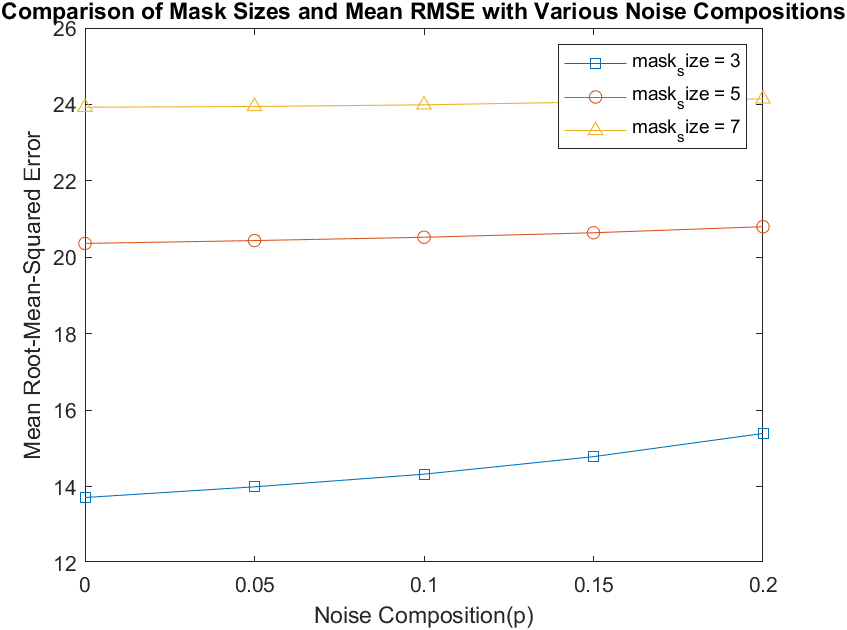

As from the graph, the line for mask size of 3 is at the bottom of the plot  by a large margin to the others all the time. Therefore, our data confirms the choice of mask size at 3 is legitimate.

### 6.2.    Choice of Threshold for mSMF

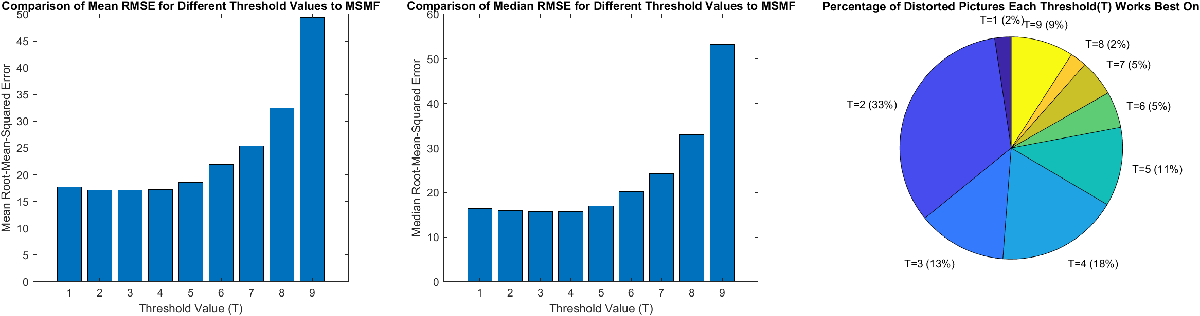


$$\left\lbrack \begin{array}{ccccc}
\textrm{Threshold}\;T & #\;\textrm{Optimal}\;\textrm{Images} & %\;\textrm{Optimal}\;\textrm{Images} & \textrm{Mean} & \textrm{Median}\\
1 & 5 & 2\ldotp 3923% & 17\ldotp 692 & 16\ldotp 409\\
2 & 70 & 33\ldotp 493% & 17\ldotp 169 & 15\ldotp 963\\
3 & 27 & 12\ldotp 919% & 17\ldotp 119 & 15\ldotp 75\\
4 & 37 & 17\ldotp 703% & 17\ldotp 214 & 15\ldotp 682\\
5 & 24 & 11\ldotp 483% & 18\ldotp 557 & 16\ldotp 986\\
6 & 11 & 5\ldotp 2632% & 21\ldotp 947 & 20\ldotp 237\\
7 & 11 & 5\ldotp 2632% & 25\ldotp 414 & 24\ldotp 298\\
8 & 5 & 2\ldotp 3923% & 32\ldotp 528 & 32\ldotp 967\\
9 & 19 & 9\ldotp 0909% & 49\ldotp 33 & 53\ldotp 297
\end{array}\right\rbrack$$


In the data we gathered, the difference between threshold of 2, 3, and 4 are minimal. While T = 2 have a lot of optimal image count, T = 3 have the best mean RMSE, and T = 4 have the best median RMSE, and all leading by a small margin. This makes the choice of threshold difficult. In the original paper, the choice is made for T = 4 as it leads in three statistics, however, the data was not that far from other thresholds either [1].

### 6.3.    Comparison between filters

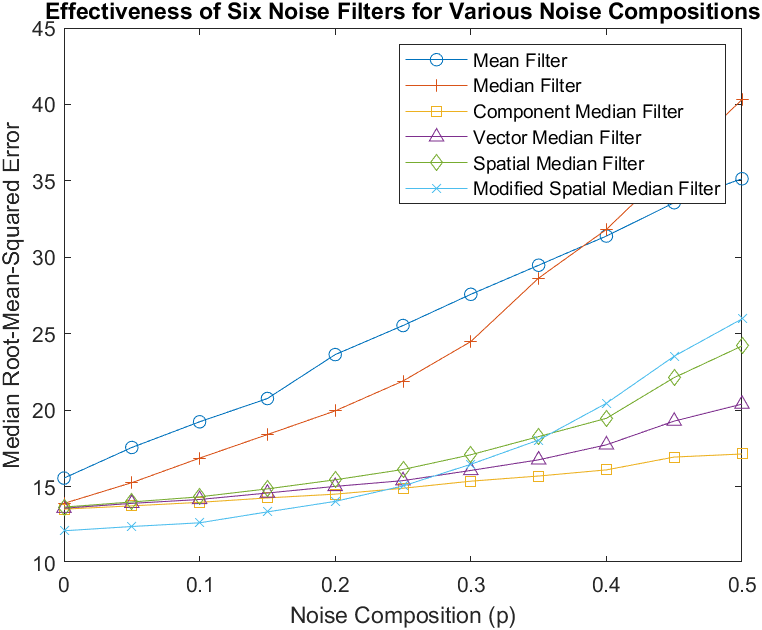

In this graph, we can see that mSMF performs the for noise composition below 0.2, which confirms with the theory and original publication about the advantage of mSMF. at large noise composition, mSMF performance decreases quickly, which also confirms with the theory of mSMF's weakness compared to other filters. The CMF is the most stable filter across different noise composition, while the mean filter behaves worst most of the time.

7.    Analysis and Conclusions

Should be alright...

8.    References and Attachements

[1]    J. C. Church, Y. Chen, and S. V. Rice, “A Spatial Median Filter for noise removal in digital images,” *IEEE **SoutheastCon** 2008*, 2008.

[2]    Script for spatial depth calculation: [sdepth.mlx](matlab:open('./sdepth.mlx'))

[3]    Script for spatial median filter: [SMF.mlx](matlab:open('./SMF.mlx'))

[4]    Script for modified spatial median filter: [MSMF.mlx](matlab:open('./MSMF.mlx'))

[5]    Script for mean filter: [MeanFilter.mlx](matlab:open('./MeanFilter.mlx'))

[6]    Script for median filter: [MedianFilter.mlx](matlab:open('./MedianFilter.mlx'))

[7]    Script for component median filter: [CMF.mlx](matlab:open('./CMF.mlx'))

[8]    Script for vector median filter: [VMF.mlx](matlab:open('./VMF.mlx'))

[9]    Script for preprocessing the dataset: [preprocessing.mlx](matlab:open('./preprocessing.mlx'))

[10]    Script for artificial noise generation: [distort.mlx](matlab:open('./distort.mlx'))

[11]    Script for RMSE between images: [RMSE.mlx](matlab:open('./RMSE.mlx'))

[12]    Script for applying mask to specific pixel: [make_mask.mlx](matlab:open('./make_mask.mlx'))

[13]    Image for graph of RMSE against noise level for different mask size: [mask_size_dataviz.png](matlab:open('./mask_size_dataviz.png'))

[14]    Image for graph of different threshold for mSMF effect on RMSE: [msmf_thres_dataviz.png](matlab:open('./msmf_thres_dataviz.png'))

[15]    Table for the data presented in threshold image: [msmf_thres_datatable.csv](matlab:open('./msmf_thres_datatable.csv'))

[16]    Image for graph of RMSE against noise level for different fillters: [filter_choice_dataviz.png](matlab:open('./filter_choice_dataviz.png'))

[17]    (not in report) Related presentation slides.